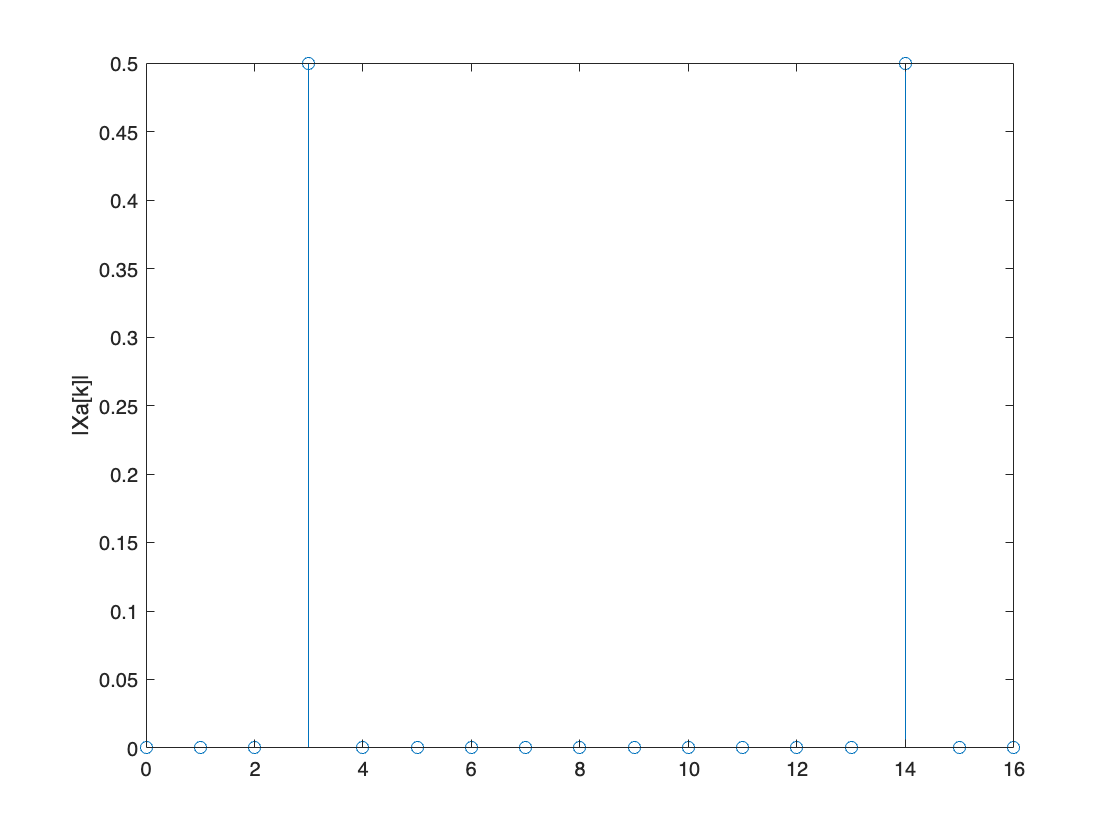

%3.103a
x = cos([0:16]*6*pi/17 + pi/3); %x[n]
X = fft(x)/17; %對x[n]做fourier轉換，N=17（一個週期）
stem(0:16,abs(X));
ylabel('|Xa[k]|');

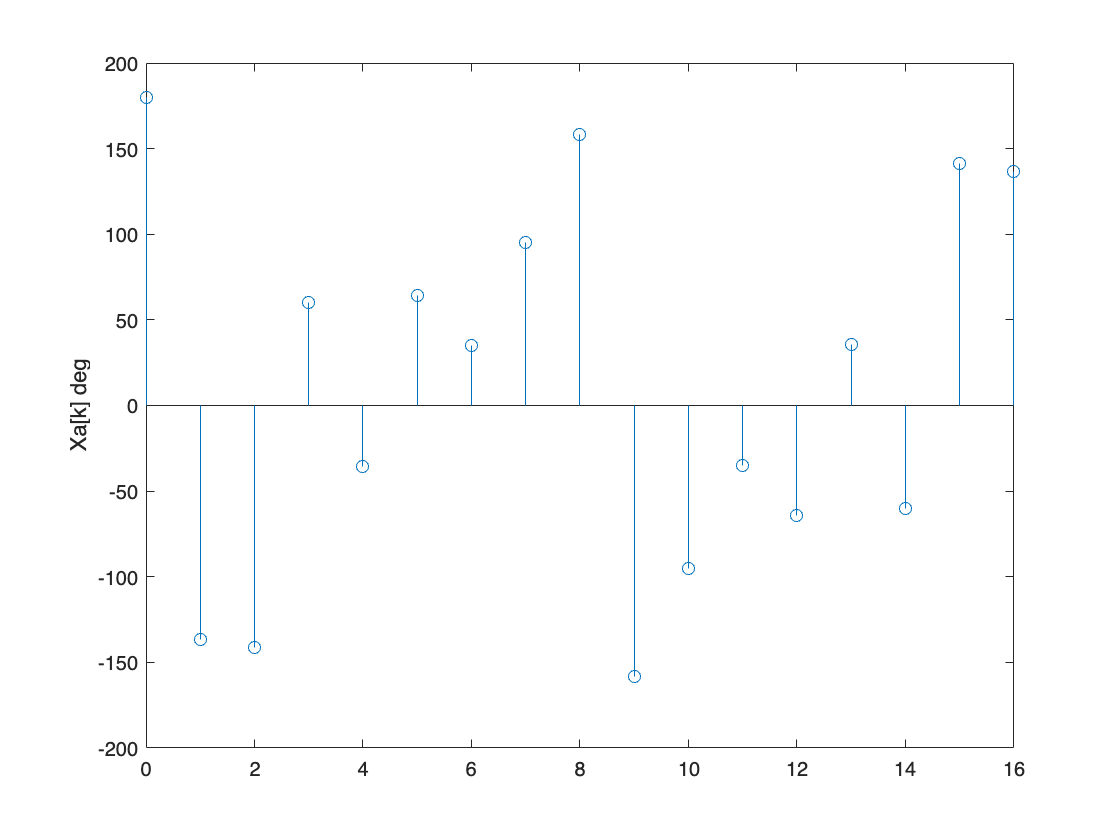

stem(0:16,rad2deg(angle(X)));
ylabel('Xa[k] deg');

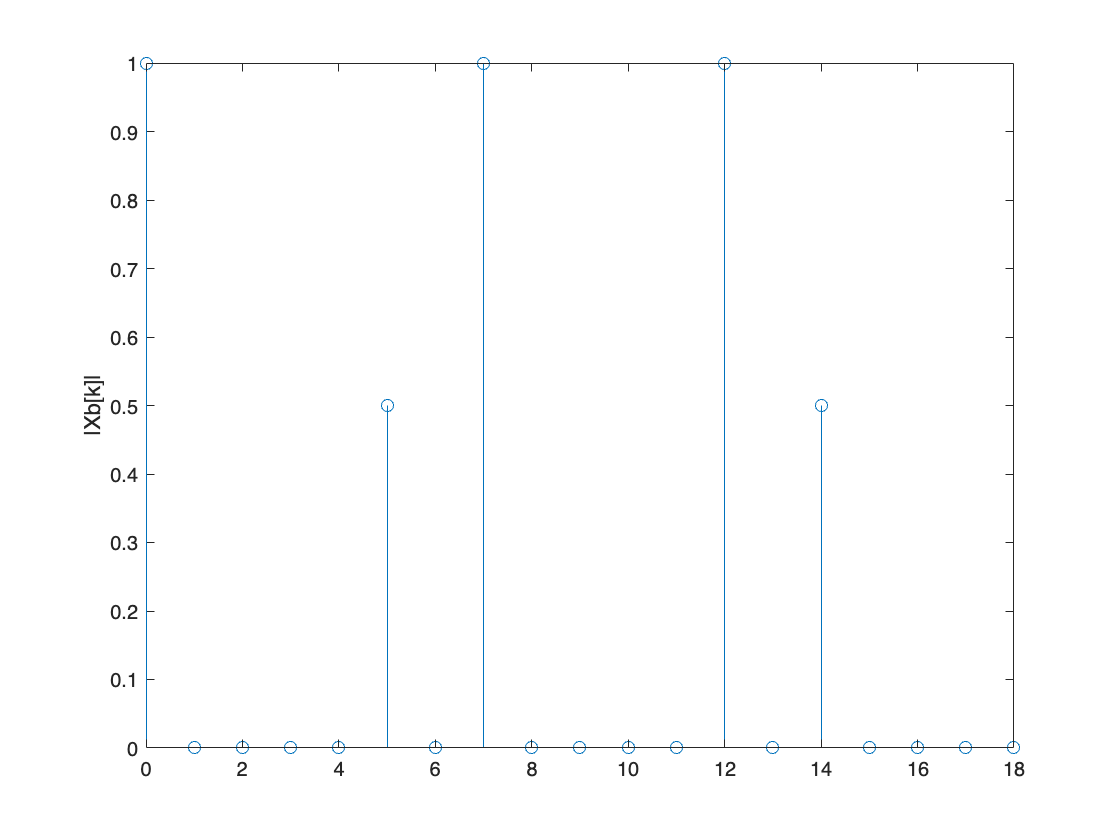

%3.103b
x = 2*sin((0:18)*14*pi/19)+cos((0:18)*10*pi/19)+ones(1,19); %x[n]
X = fft(x)/19; %對x[n]做fourier轉換，N=19（一個週期）
stem(0:18,abs(X));
ylabel('|Xb[k]|');

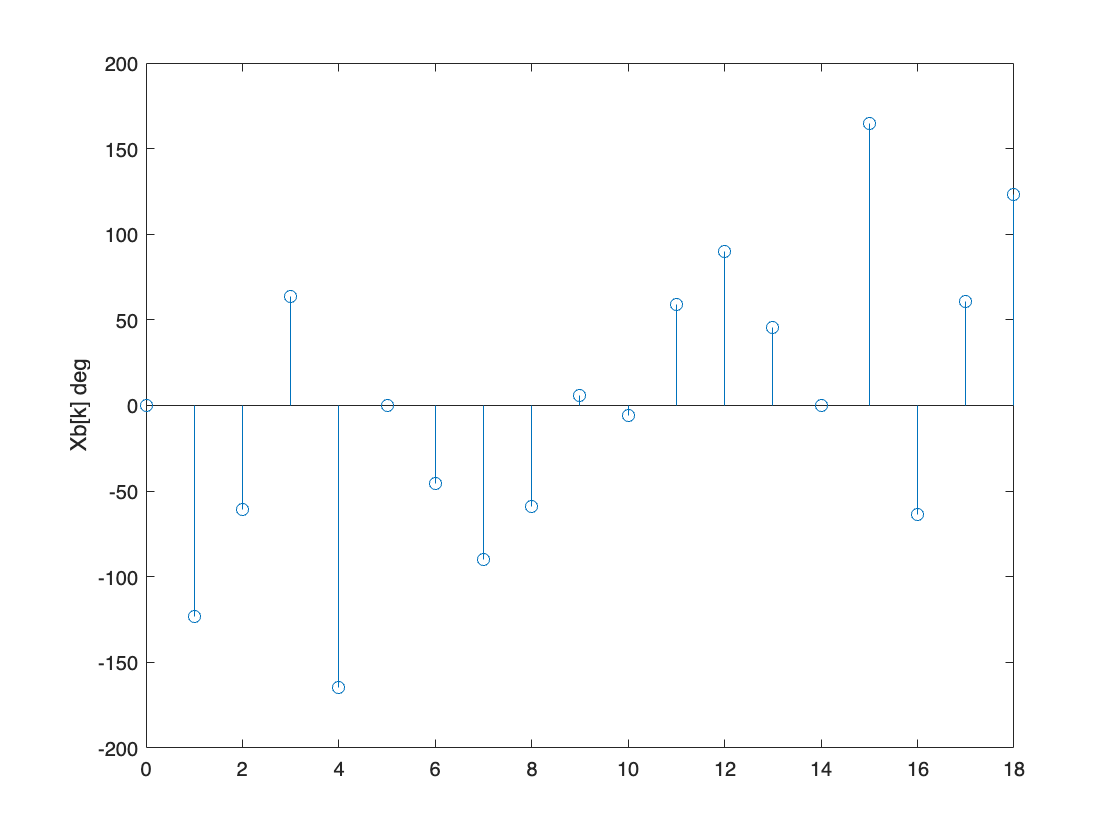

stem(0:18,rad2deg(angle(X)));
ylabel('Xb[k] deg');

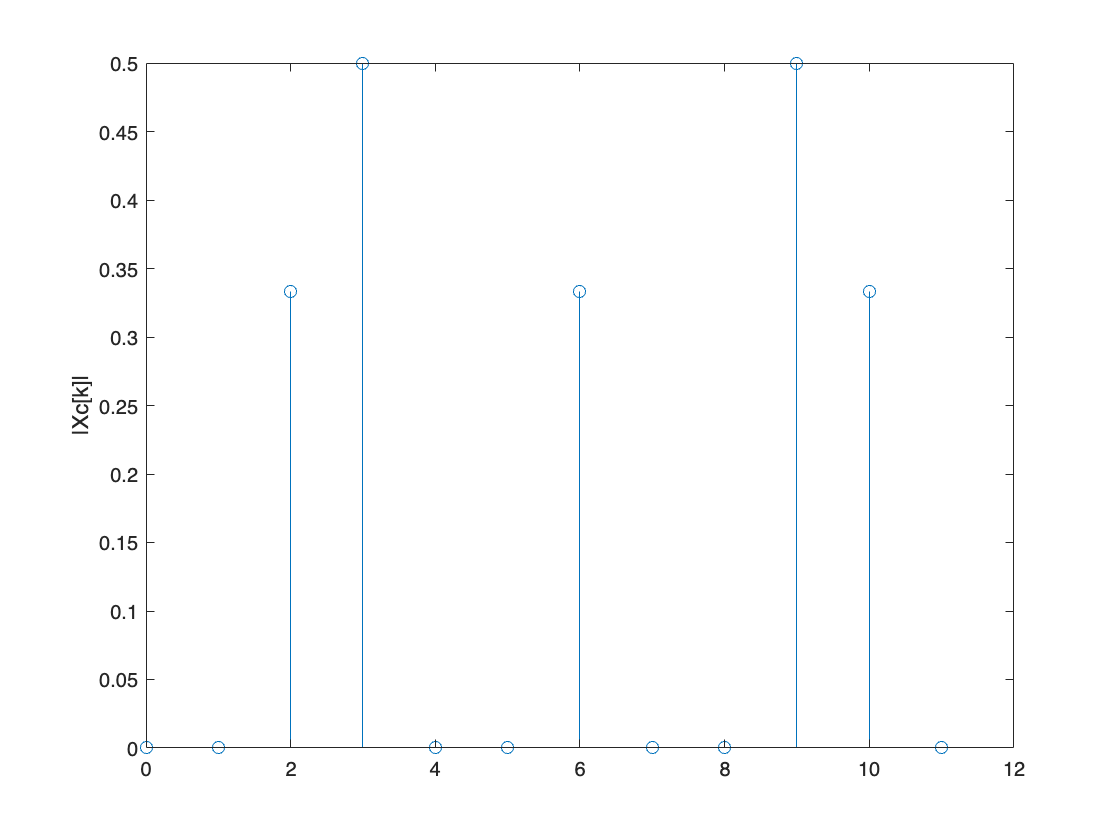

%3.103c
x=[2,0,-1,-1,1,0,0,0,1,-1,-1,0]; %x[n]
X = fft(x)/12; %對x[n]做fourier轉換，N=12（一個週期）
stem(0:11,abs(X));
ylabel('|Xc[k]|');

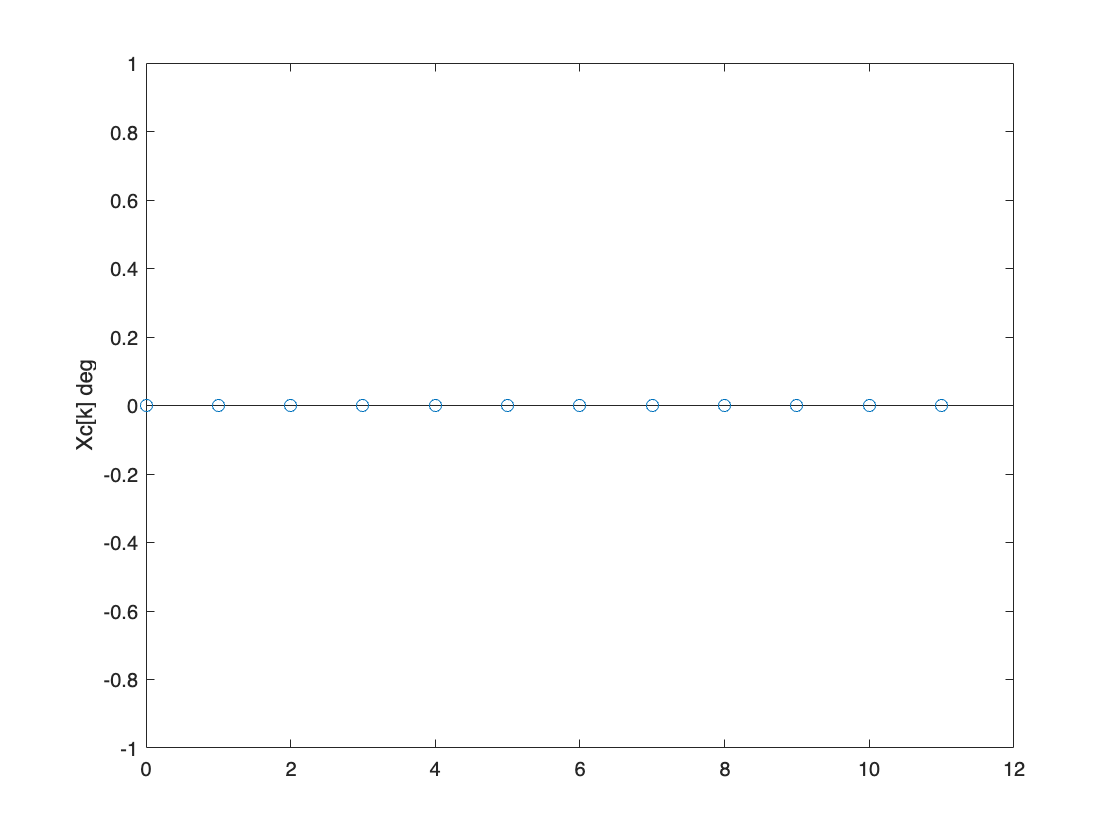

stem(0:11,rad2deg(angle(X)));
ylabel('Xc[k] deg');

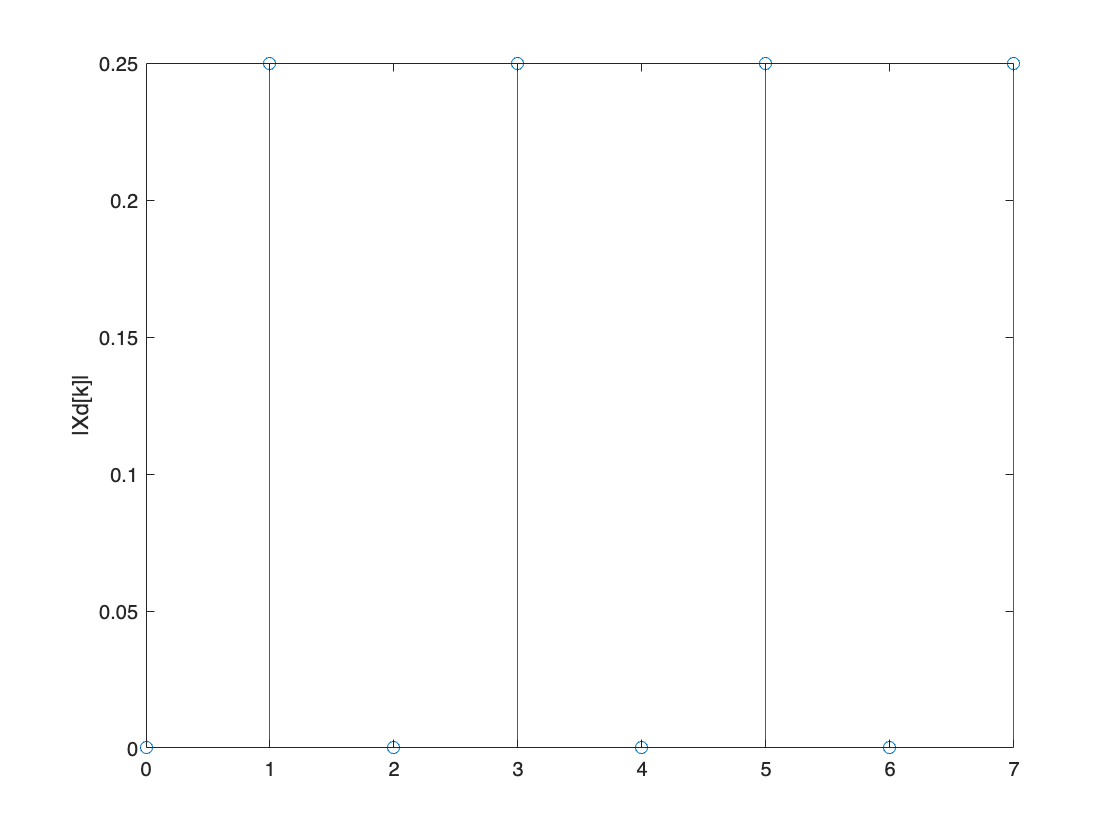

%3.103d
x=[0,0,1,0,0,0,-1,0]; %x[n]
X = fft(x)/8; %對x[n]做fourier轉換，N=8（一個週期）
stem(0:7,abs(X));
ylabel('|Xd[k]|');

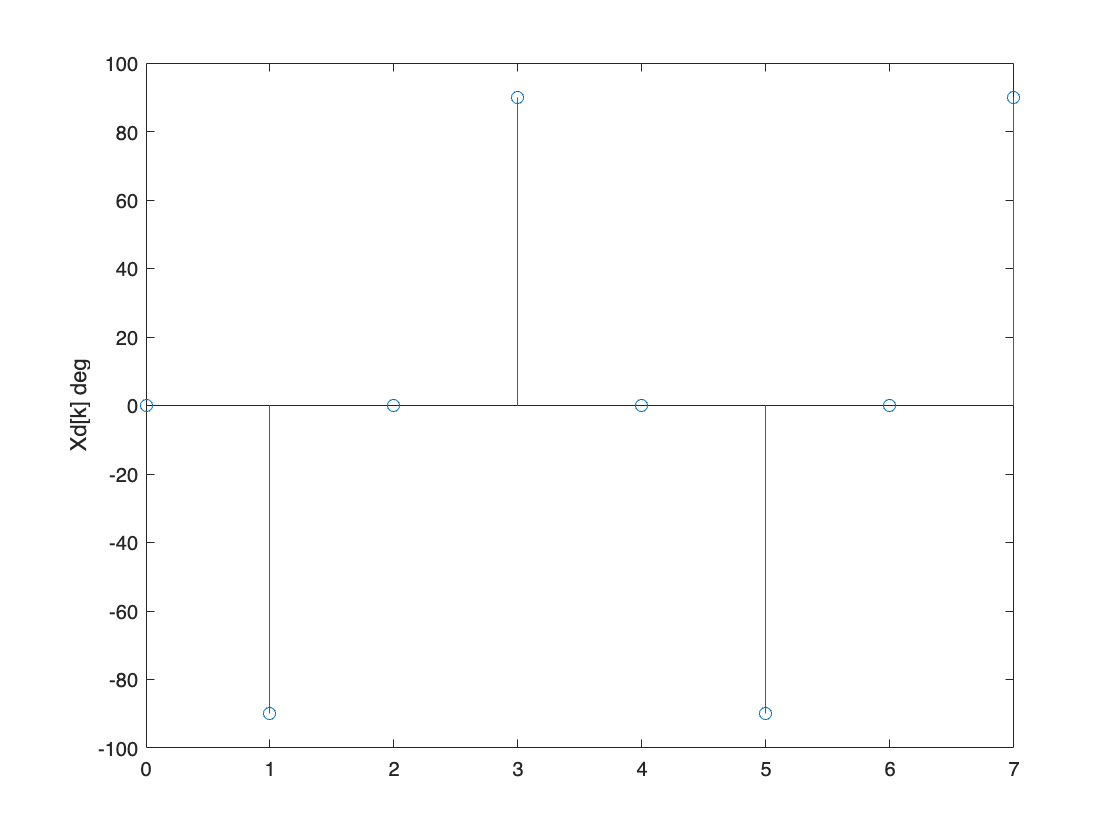

stem(0:7,rad2deg(angle(X)));
ylabel('Xd[k] deg');

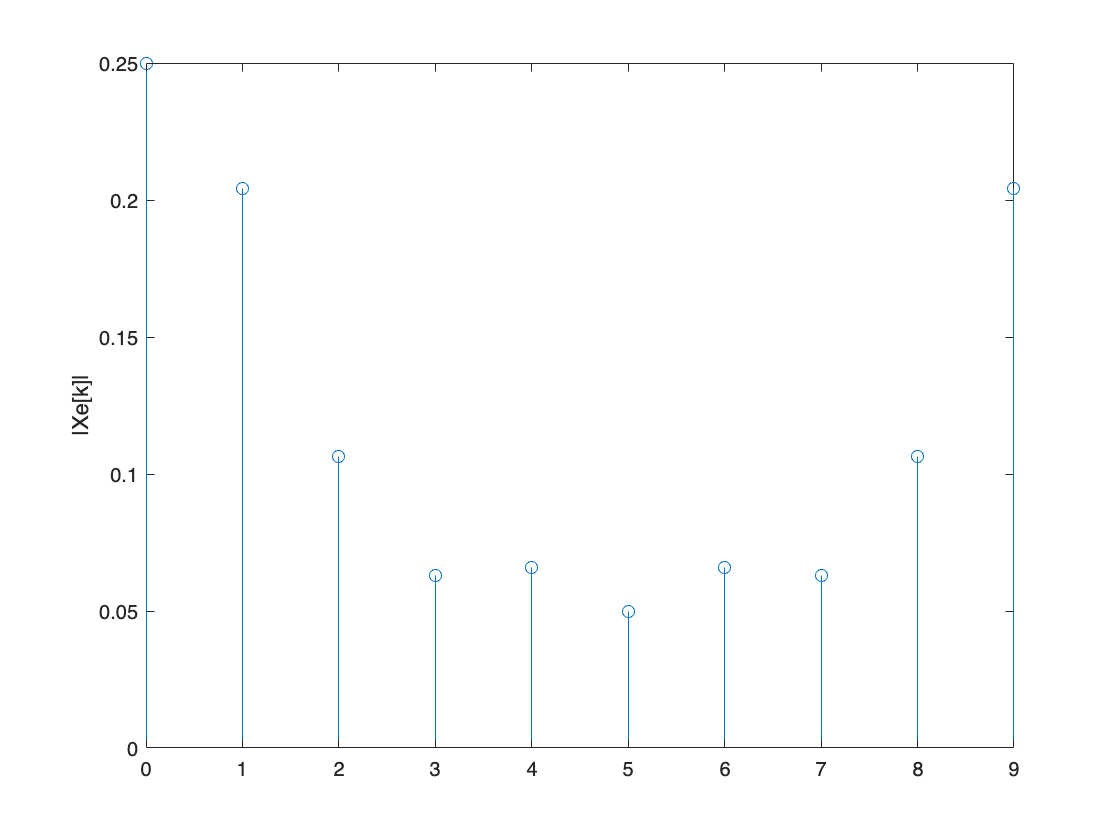

%3.103e
x=[0,0,0,0,0,0,1/4,1/2,3/4,1]; %x[n]
X = fft(x)/10; %對x[n]做fourier轉換，N=10（一個週期）
stem(0:9,abs(X));
ylabel('|Xe[k]|');

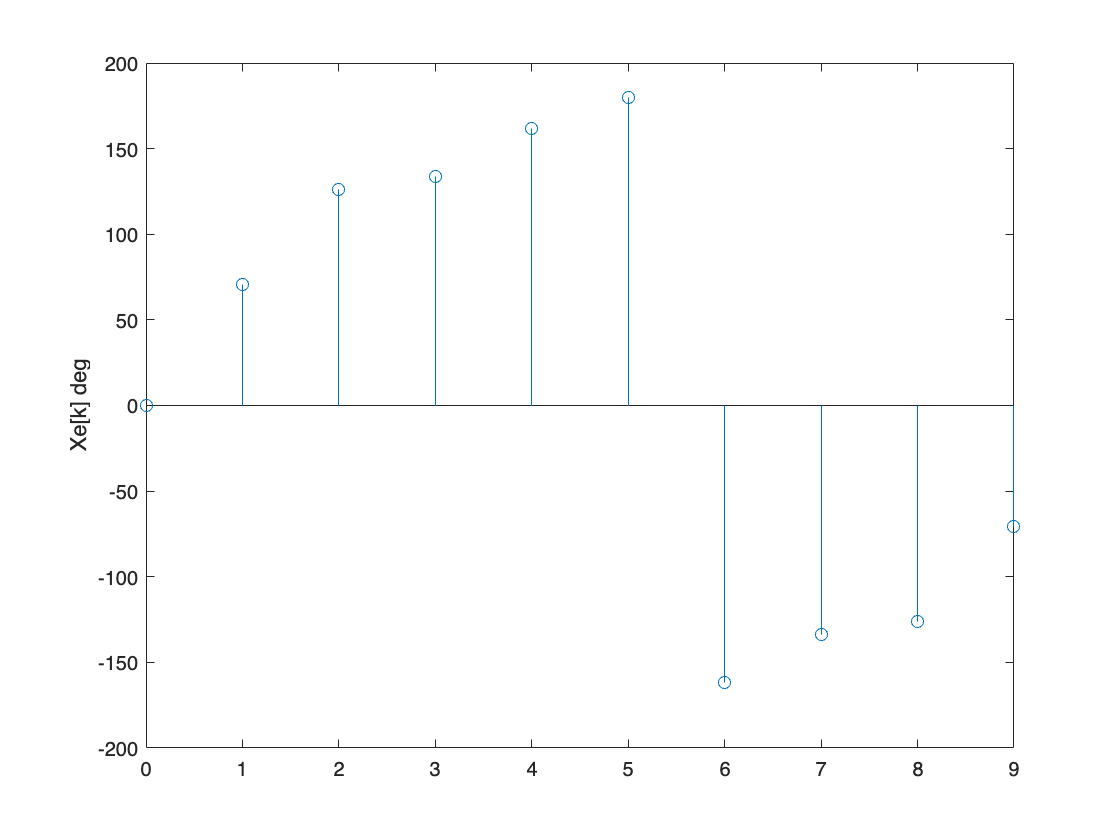

stem(0:9,rad2deg(angle(X)));
ylabel('Xe[k] deg');

%3.109a
k = 1:1:100;
t = linspace(-0.5,0.5,400);
Y = zeros(1,100);
RC=0.01;
Y(1)=0;
Y(2:1:101) = (1/RC)./(1i*pi*k*2+(1/RC)).*sin(k*pi/2)./(k*pi); % % coefficient for k
yJhat(1,:) = Y(1).*exp(1i*pi*2*0*t); % term in sum for k=0
% accumulate partial sum 
for k = 2:1:100
Yexp(k,:) = Y(k).*exp(1i*pi*(k-1)*2*t);
yJhat(k,:) = yJhat(k-1,:)+Y(k).*exp(1i*pi*(k-1)*2*t);
end
j = 100;
plot(t,yJhat(j,:));

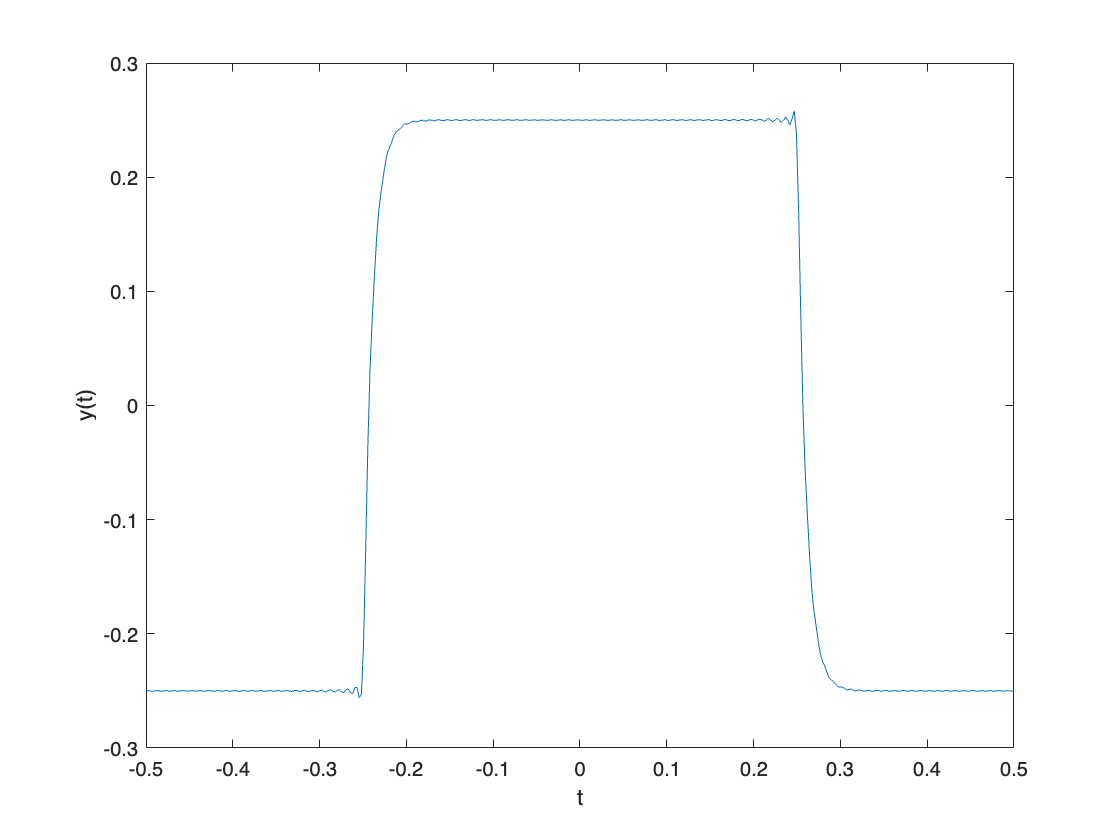

ylabel(['y(t)']);
xlabel('t');

%3.109b
k = 1:1:100;
t = linspace(-0.5,0.5,400);
Y = zeros(1,100);
RC=0.1;
Y(1)=0;
Y(2:1:101) = (1/RC)./(1i*pi*k*2+(1/RC)).*sin(k*pi/2)./(k*pi); % % coefficient for k
yJhat(1,:) = Y(1).*exp(1i*pi*2*0*t); % term in sum for k=0
% accumulate partial sum 
for k = 2:1:100
Yexp(k,:) = Y(k).*exp(1i*pi*(k-1)*2*t);
yJhat(k,:) = yJhat(k-1,:)+Y(k).*exp(1i*pi*(k-1)*2*t);
end
j = 100;
plot(t,yJhat(j,:));

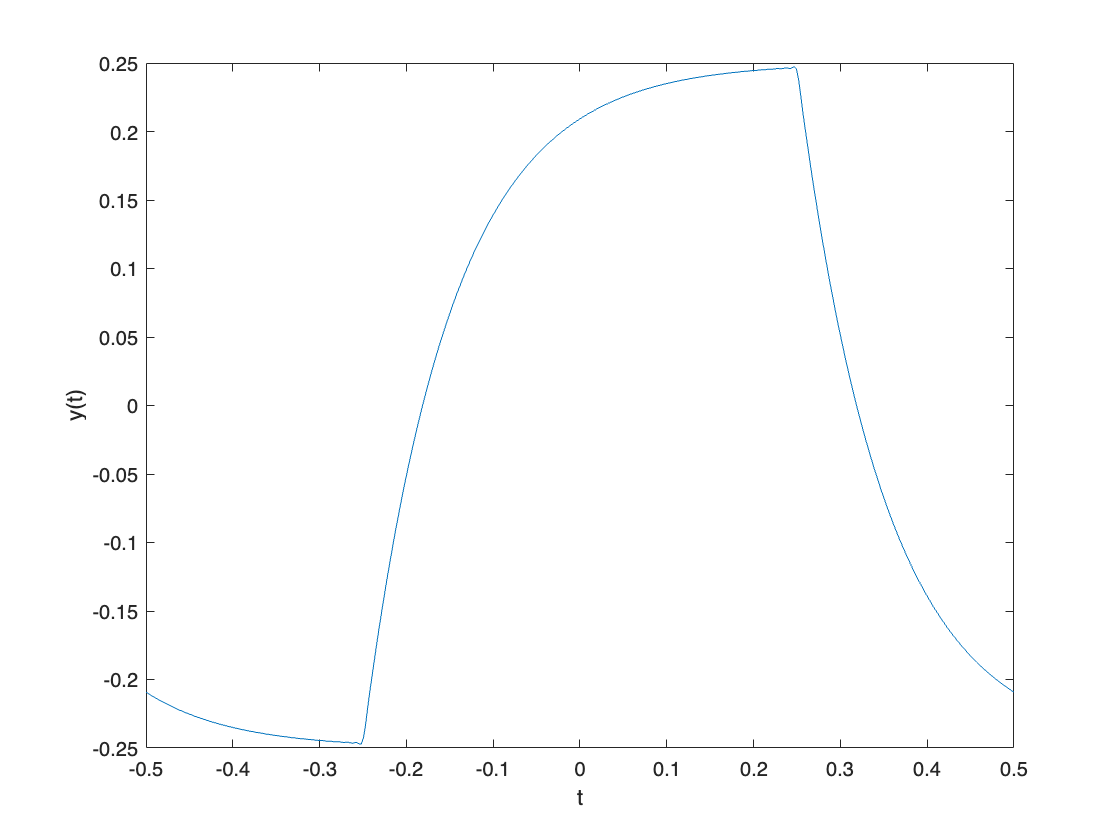

ylabel(['y(t)']);
xlabel('t');

%3.109c
k = 1:1:100;
t = linspace(-0.5,0.5,400);
Y = zeros(1,100);
RC=1;
Y(1)=0;
Y(2:1:101) = (1/RC)./(1i*pi*k*2+(1/RC)).*sin(k*pi/2)./(k*pi); % % coefficient for k
yJhat(1,:) = Y(1).*exp(1i*pi*2*0*t); % term in sum for k=0
% accumulate partial sum 
for k = 2:1:100
Yexp(k,:) = Y(k).*exp(1i*pi*(k-1)*2*t);
yJhat(k,:) = yJhat(k-1,:)+Y(k).*exp(1i*pi*(k-1)*2*t);
end
j = 100;
plot(t,yJhat(j,:));

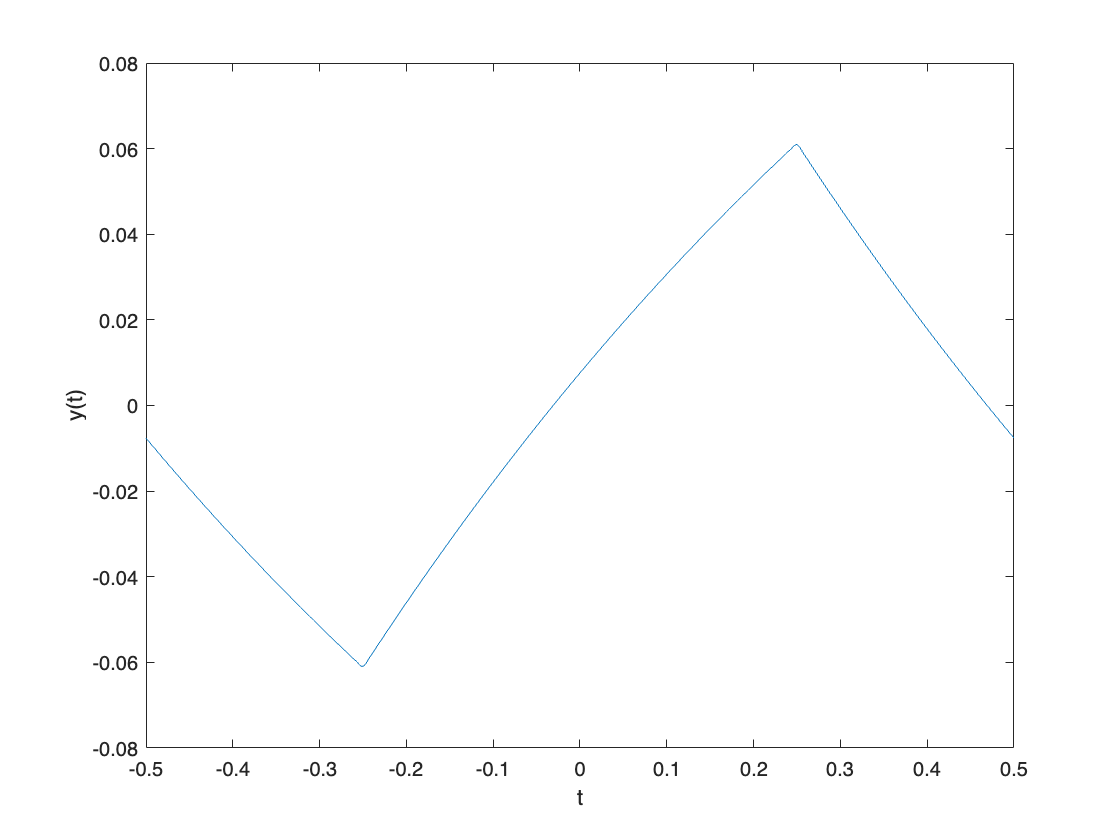

ylabel(['y(t)']);
xlabel('t');

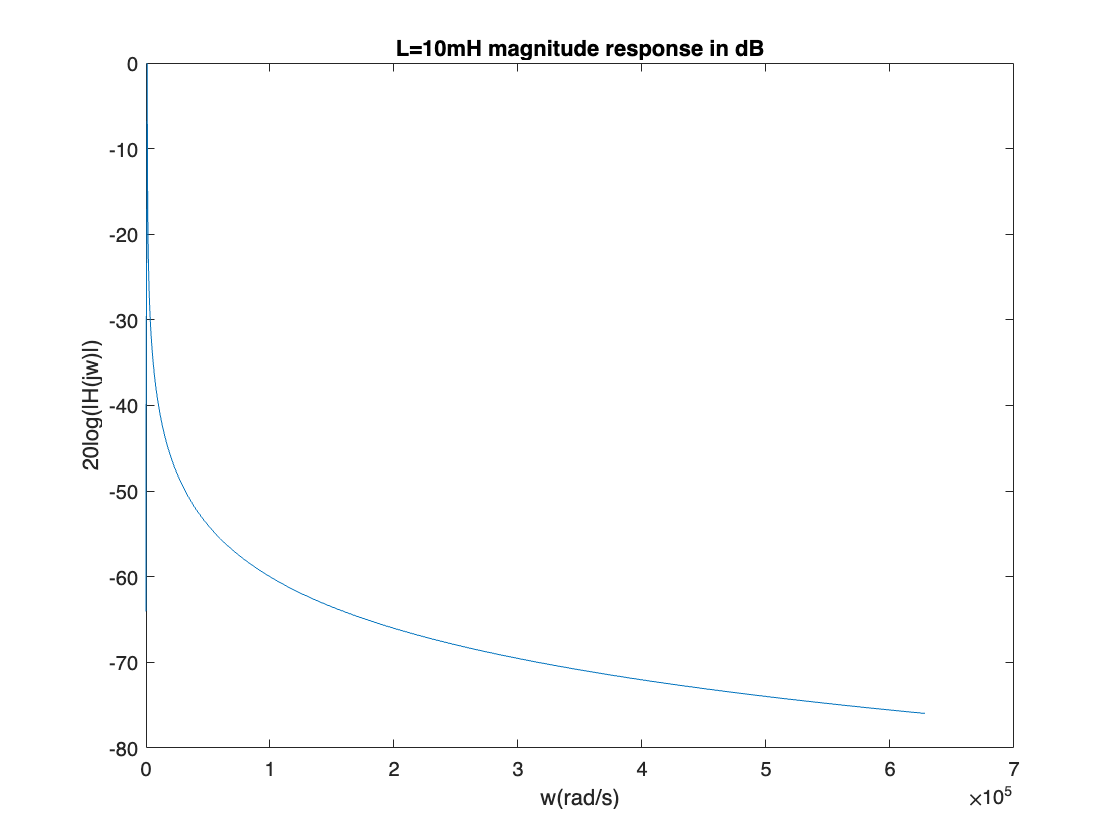

%3.111a1
f= logspace(0, 5, 501);
C= 100*(10.^(-6));
L= 10*(10.^(-3));
w= 2*pi*f;
s= 1i*w;
H= s./ (s.^2*L + s + 1/C); %transfer function of the bandpass filter
magnitude = 20*log10(abs(H));
plot(w, magnitude);
xlabel('w(rad/s)');
ylabel('20log(|H(jw)|)');
title('L=10mH magnitude response in dB');

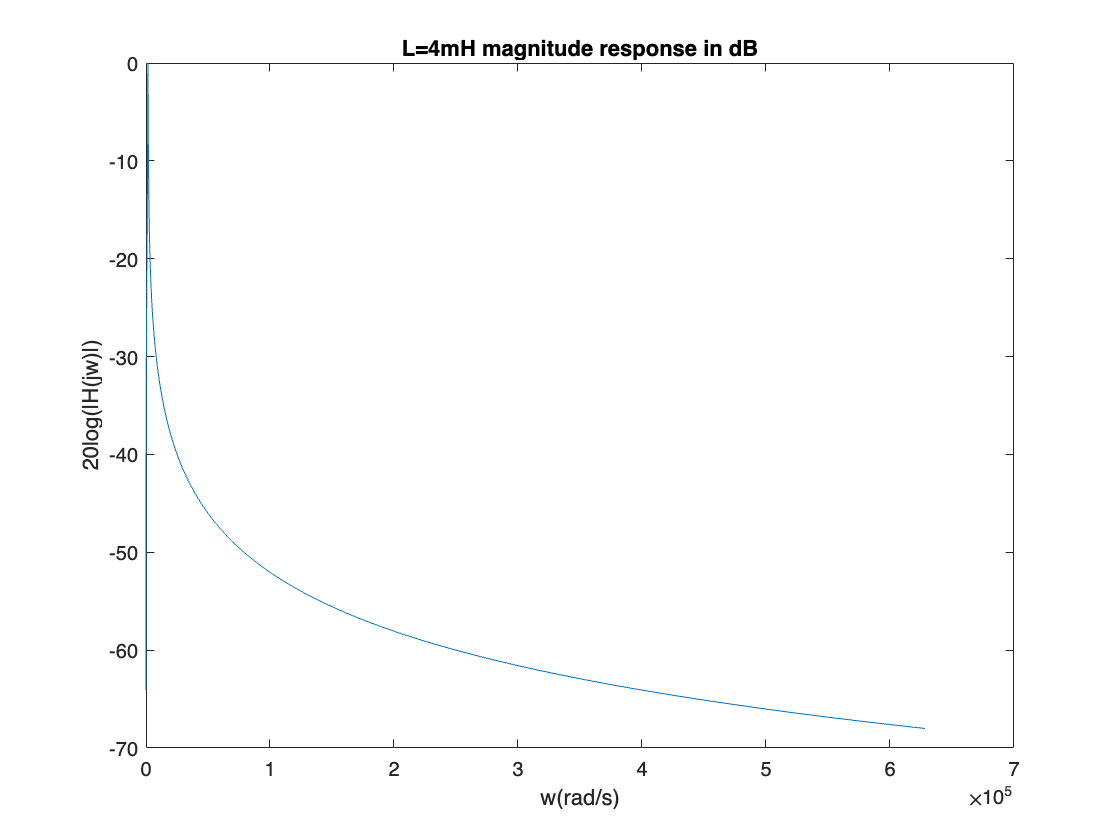

%3.111a2
f= logspace(0, 5, 501);
C= 100*(10.^(-6));
L= 4*(10.^(-3));
w= 2*pi*f;
s= 1i*w;
H= s./ (s.^2*L + s + 1/C); %transfer function of the bandpass filter
magnitude = 20*log10(abs(H));
plot(w, magnitude);
xlabel('w(rad/s)');
ylabel('20log(|H(jw)|)');
title('L=4mH magnitude response in dB');

%3.111b1
k = 1:1:50;
C= 100*(10.^(-6));
L= 10*(10.^(-3));
w= 1000;
s= 1i*w*k;
H= s./ (s.^2*L + s + 1/C); %transfer function of the bandpass filter
T0=pi./2000;
T=pi./500;
t = linspace(-pi*10.^(-3),pi*10.^(-3),400);
Y = zeros(1,50);
Y(1)=0;
Y(2:1:51) = H.*(sin(k*w*T0)*2)./(k*w*T); ; % coefficient for k!=0
yJhat(1,:) = Y(1).*exp(1i*w*0*t); % term in sum for k=0
% accumulate partial sum 
for k = 2:1:50
Yexp(k,:) = Y(k).*exp(1i*(k-1)*w*t);
yJhat(k,:) = yJhat(k-1,:)+Y(k).*exp(1i*w*(k-1)*t);
end
j = 50;
plot(t,yJhat(j,:));

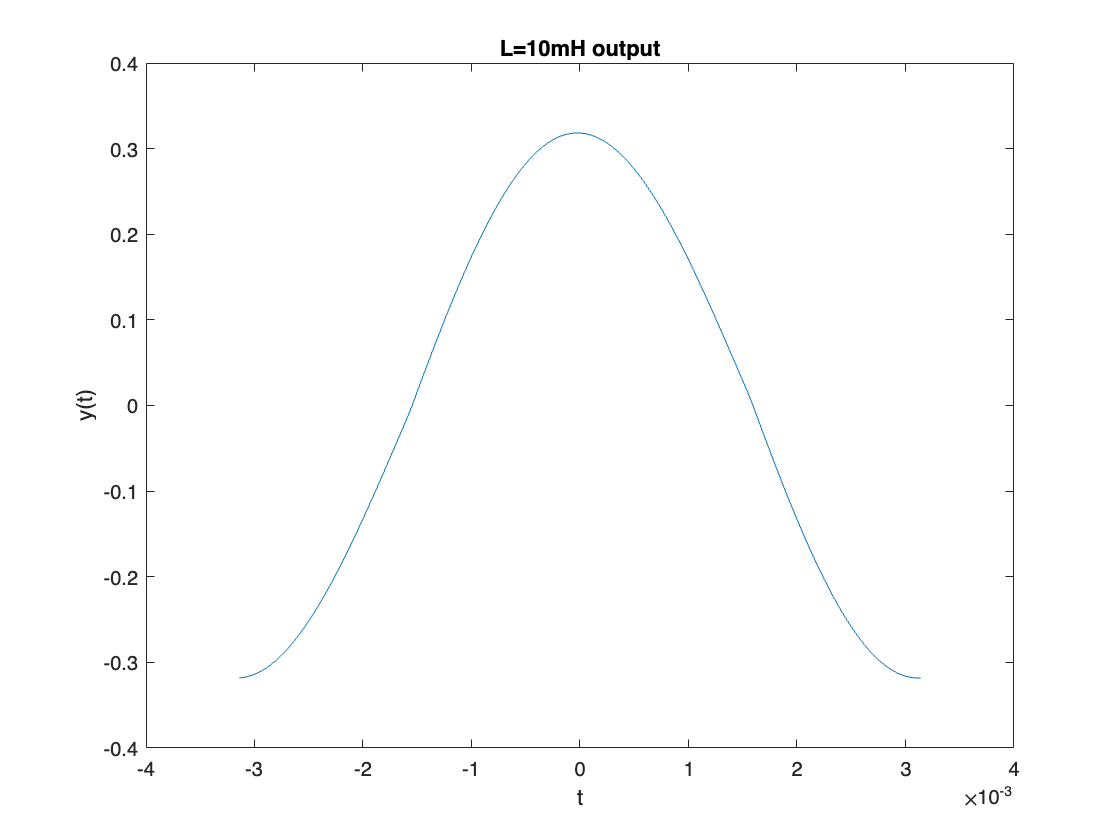

ylabel(['y(t)']);
xlabel('t');
title('L=10mH output');

%3.111b2
k = 1:1:50;
C= 100*(10.^(-6));
L= 4*(10.^(-3));
w= 1000;
s= 1i*w*k;
H= s./ (s.^2*L + s + 1/C); %transfer function of the bandpass filter
T0=pi./2000;
T=pi./500;
t = linspace(-pi*10.^(-3),pi*10.^(-3),400);
Y = zeros(1,50);
Y(1)=0;
Y(2:1:51) = H.*(sin(k*w*T0)*2)./(k*w*T); ; % coefficient for k!=0
yJhat(1,:) = Y(1).*exp(1i*w*0*t); % term in sum for k=0
% accumulate partial sum 
for k = 2:1:50
Yexp(k,:) = Y(k).*exp(1i*(k-1)*w*t);
yJhat(k,:) = yJhat(k-1,:)+Y(k).*exp(1i*w*(k-1)*t);
end
j = 50;
plot(t,yJhat(j,:));

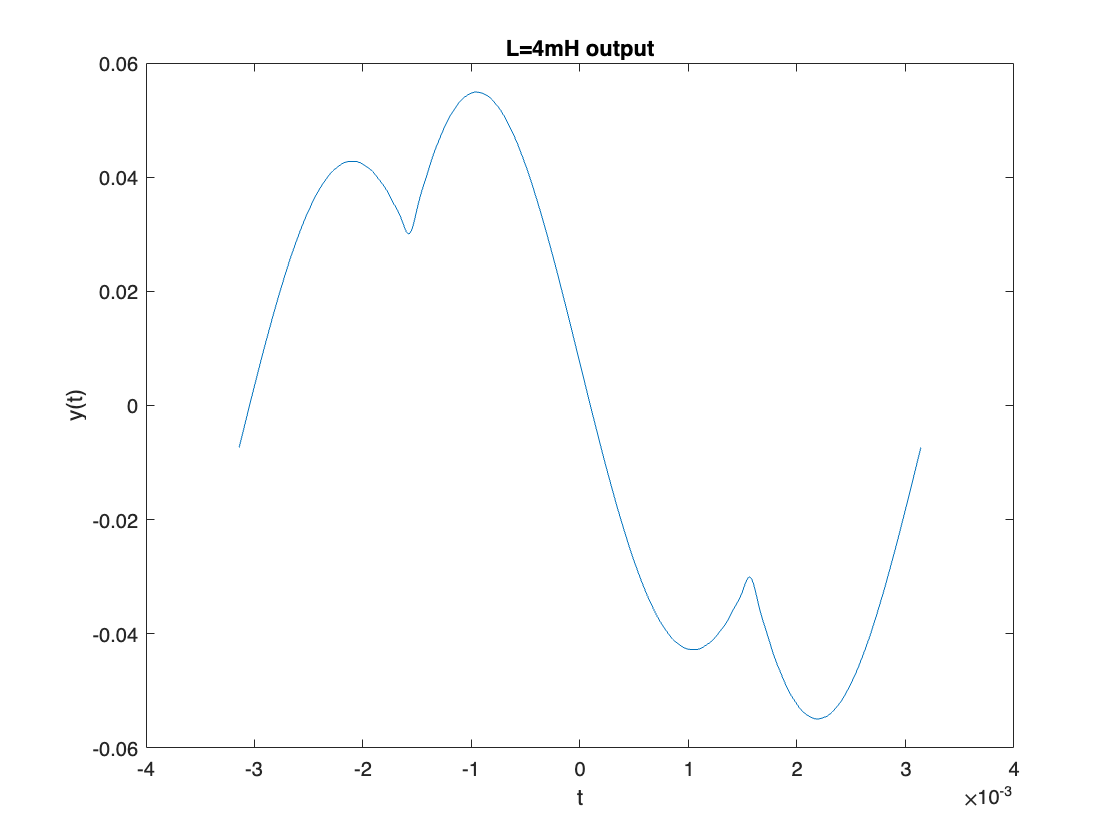

ylabel(['y(t)']);
xlabel('t');
title('L=4mH output');

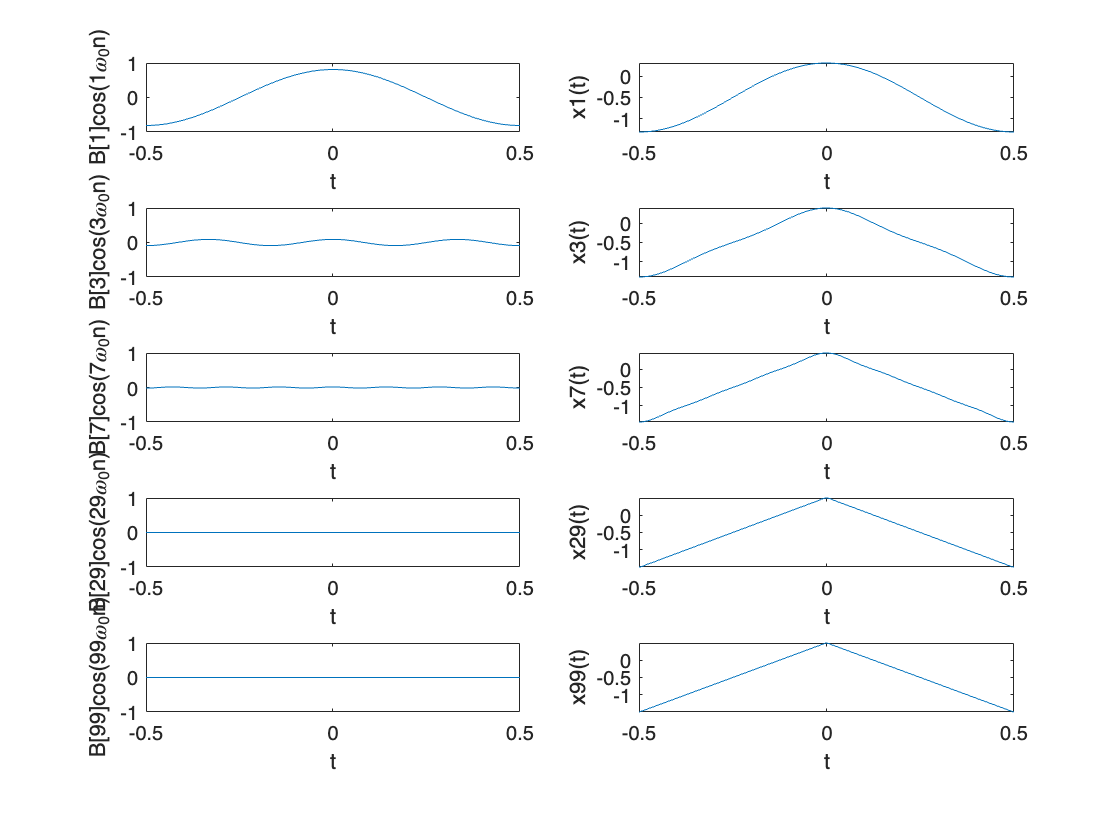

%3.107
k = 1:1:99;
t = linspace(-0.5,0.5,400);%generates a row vector of 400 evenly spaced points between -0.5 and 0.5
B = zeros(1,100);
B(1) = -0.5; % coefficient for k=0
B(2:1:100) = 8*sin(k*pi/2).*exp(1i*pi*(k-1)/2)./((pi*k).^2); % coefficient for k!=0
xJhat(1,:) = B(1)*cos(0*2*pi*t); % term in sum for k=0
% accumulate partial sum 
for k = 2:1:100
Bcos(k,:) = B(k)*cos((k-1)*2*pi*t);
xJhat(k,:) = xJhat(k-1,:)+B(k)*cos((k-1)*2*pi*t);
end
j = [1 3 7 29 99]+1;
for i = 1:1:5
subplot(5,2,2*i-1);plot(t,Bcos(j(i),:));
ylabel(['B[' num2str(j(i)-1) ']cos(' num2str(j(i)-1) '\omega_0n)']);
xlabel('t');axis([-0.5 0.5 -1 1]);
subplot(5,2,2*i);plot(t,xJhat(j(i),:));
ylabel(['x' num2str(j(i)-1) '(t)']);
xlabel('t');
end